% [robot, imInfo] = importrobot("./cad_models/version_1/RRS_2RRU_Robot/urdf/RRS_2RRU_Robot.urdf");
% [robot, imInfo] = importrobot("RRS_2RRU_Open.slx");
% show(robot,"Visuals","on");

初始化

%m
%% ver1
% R = 80*1e-3;
% r = 80*1e-3;
% L1 = 160*1e-3;
% L2 = 192*1e-3; 
% toolHight = 132*1e-3;
% z_p_min = 193.46*1e-3;

%% ver2
R = 104*1e-3;
r = 104*1e-3;
L1 = 208*1e-3;
L2 = 249.6*1e-3; 
toolHight = 136.8*1e-3;
z_p_min = 201.937*1e-3;

RRS_2RRU = RRS_2RRU_Basic(R, r, L1, L2, toolHight, z_p_min);

RRS_2RRU.z_p_max %max hight

ans = 0.4576

RRS_2RRU.z_p_operation %operation hight

ans = 0.3298

RRS_2RRU.delta_z_p %route

ans = 0.2557


%% set spindle mass
spindle_mass = 5.25; %kg
spindle_mass_center_p = [0; 0; -46.3]*1e-3; %m
RRS_2RRU.setSpindleMass(spindle_mass, spindle_mass_center_p);

分层工作空间

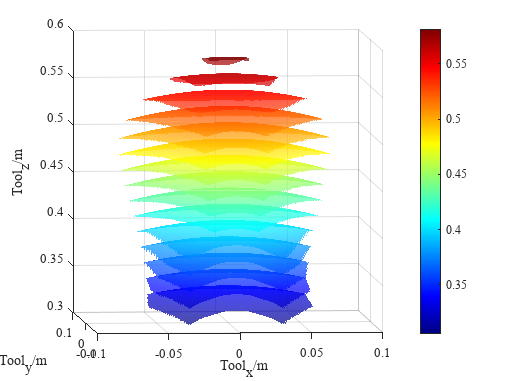

[~, z_p_slices, maxAreaId] = RRS_2RRU.plotToolWorkSpace([RRS_2RRU.z_p_min, RRS_2RRU.z_p_max-0.05*RRS_2RRU.delta_z_p], ...
                [-pi/6,pi/6], [-pi/6,pi/6], 15);


disp("max working area at (m):");
disp(z_p_slices(maxAreaId));
[Tf_BTC, Tf_P] = RRS_2RRU.setEndEffectorSE3(z_p_slices(maxAreaId), 0, 0);
thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine
disp("thetas (degree):");
disp(rad2deg(thetas));

测试极限位姿

%[z_p, alpha, beta]
test_pose = [z_p_min, 0, 0;
            z_p_min, 0, pi/6;
            z_p_min+50*1e-3, 0, pi/6;
            z_p_min+50*1e-3, pi/6, 0;
            z_p_min+50*1e-3, -pi/6, 0;
            z_p_min+100*1e-3, 0, pi/6;
            z_p_min+100*1e-3, pi/6, 0;
            RRS_2RRU.z_p_operation, 0, pi/6;
            RRS_2RRU.z_p_operation, pi/6, 0]; 

for i=1:size(test_pose, 1)
    curPose = test_pose(i, :);
    [Tf_BTC, Tf_P] = RRS_2RRU.setEndEffectorSE3(curPose(1), curPose(2), curPose(3));
    thetas = RRS_2RRU.invKineUpdate(Tf_BTC); %invkine
    rad2deg(thetas)
end

给定主轴重量、切削力，求关节力矩在工作空间的力分布：

计算交变力

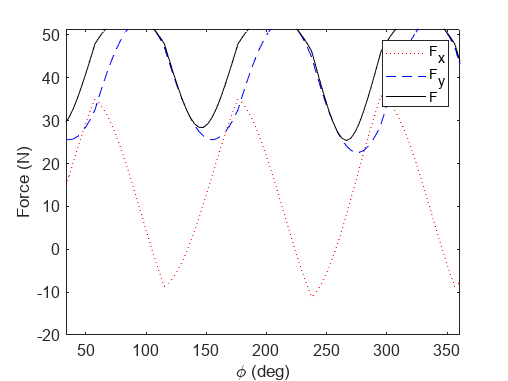

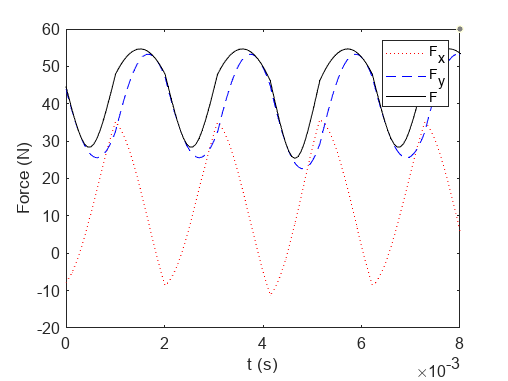

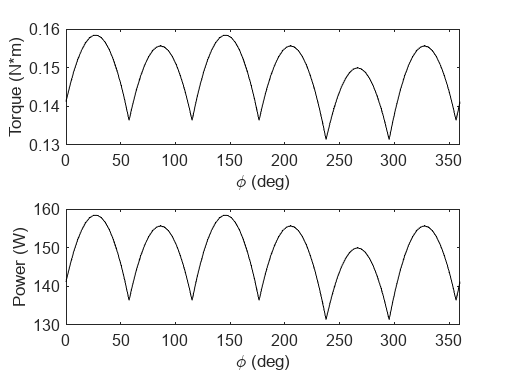

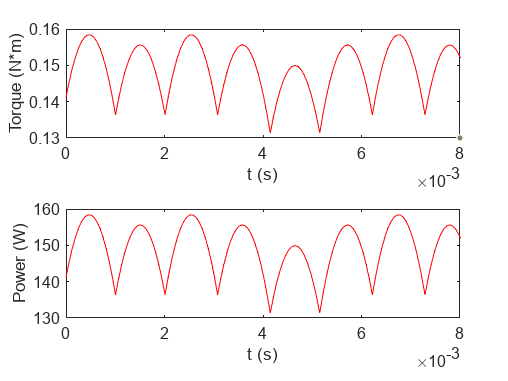

% 参数
Ks=791;
beta=71.6;
a_p = 1.2;
feedRate = 1650/60; %mm/s
d = 6;
Nt = 3;
omega = 9549;

% 理论交变切削力
steps = 100;
[Force_x, Force_y, Force, Torque, Power, t, phi] = getSlotMillingForce(Ks, beta, a_p, ...
                                                    feedRate, d, Nt, omega, steps, true);

F_max = max(Force)

F_max = 54.6717


% % 经验公式切削力
% F_c = roughMillingForce(feedRate, Nt, d, a_p, d, omega);
% 
% % 修正交变力
% k_m = F_c/F_max;
% Force_x_m = k_m*Force_x;
% Force_y_m = k_m*Force_y;
% Force_m = k_m*Force;
% Torque_m = k_m*Torque;
% Power_m = k_m*Power;
% 
% % plot
% figure(1)
% plot(t, Force_x_m, 'r:', t, Force_y_m, 'b--', t, Force_m, 'k')
% % axis([0 0.008 -150 400])
% xlim([0 0.008]);
% set(gca,'FontSize', 12)
% xlabel('t (s)')
% ylabel('Force (N)')
% legend('F_x', 'F_y', 'F')
% 
% %x--t
% figure;
% subplot(2,1,1);
% plot(t, Torque_m, 'r');
% xlim([0 0.008]);
% set(gca,'FontSize', 12)
% xlabel('t (s)')
% ylabel('Torque (N*m)')
% 
% subplot(2,1,2);
% plot(t, Power_m, 'r');
% xlim([0 0.008]);
% set(gca,'FontSize', 12)
% xlabel('t (s)')
% ylabel('Power (W)')

三轴平衡力矩在工作空间中的分布：

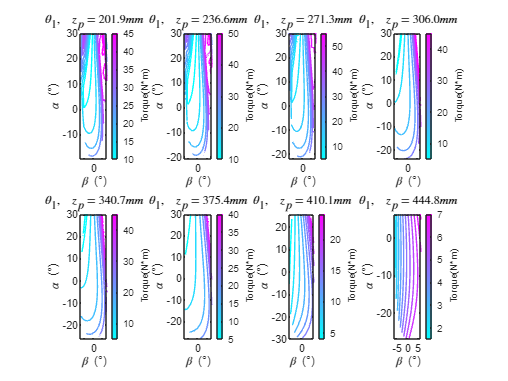

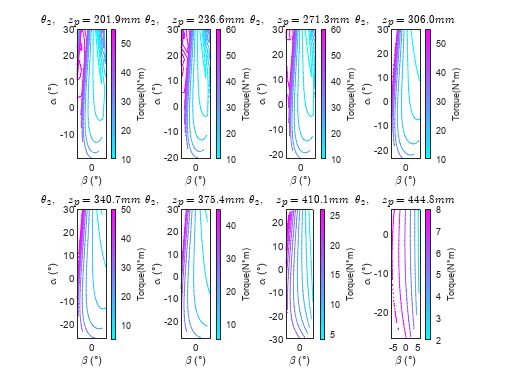

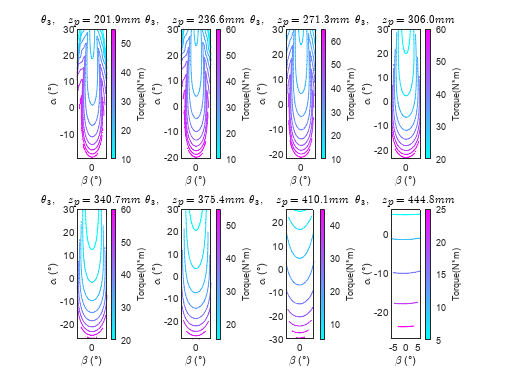

%切削力截取
% Force_x_m = Force_x_m(1:0.5*steps);
% Force_y_m = Force_y_m(1:0.5*steps);
% Torque_m = Torque_m(1:0.5*steps);

Force_x = Force_x(1:0.5*steps);
Force_y = Force_y(1:0.5*steps);
Torque = Torque(1:0.5*steps);

%三轴平衡力矩在工作空间中的分布
RRS_2RRU.gravity = [0;-9.8;0]; %gravity direction

% wrench_len = length(Torque_m);
% wrench = [zeros(2, wrench_len); Torque_m; Force_x_m; Force_y_m; zeros(1, wrench_len)];
wrench_len = length(Torque);
wrench = [zeros(2, wrench_len); Torque; Force_x; Force_y; zeros(1, wrench_len)];

zp_range = [RRS_2RRU.z_p_min, RRS_2RRU.z_p_max-0.05*RRS_2RRU.delta_z_p];
alpha_range = [-pi/6,pi/6];
beta_range = [-pi/6,pi/6];
N_zp = 8;

[f, maxActInfo] = plotMaxActuationSpace(RRS_2RRU, wrench, zp_range, alpha_range, beta_range, N_zp);